# Transformation Functions

## 1D translation

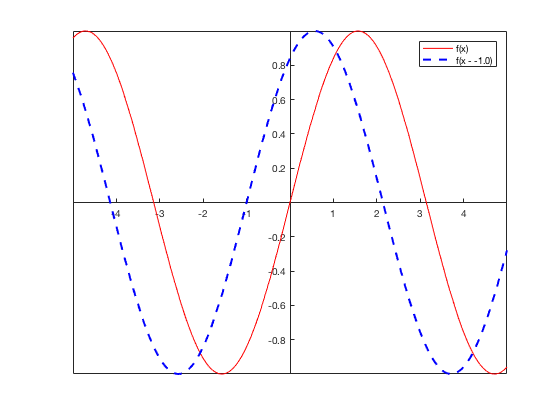

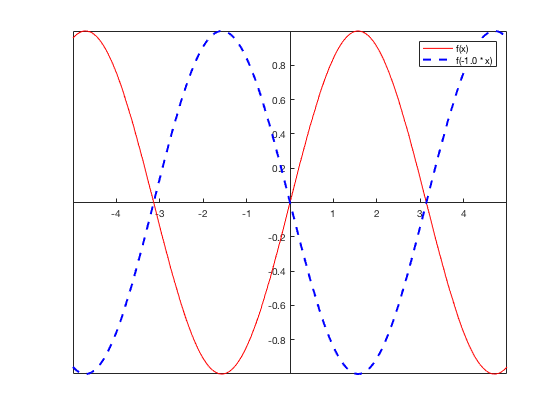

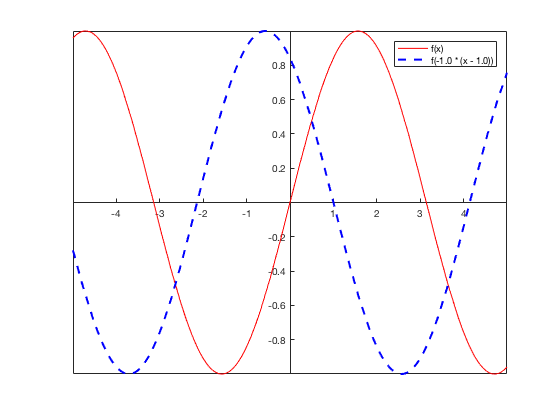

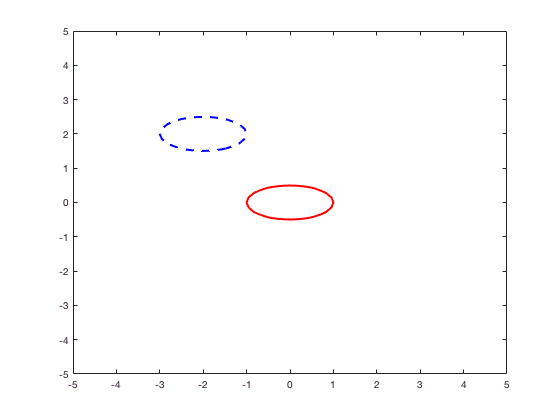

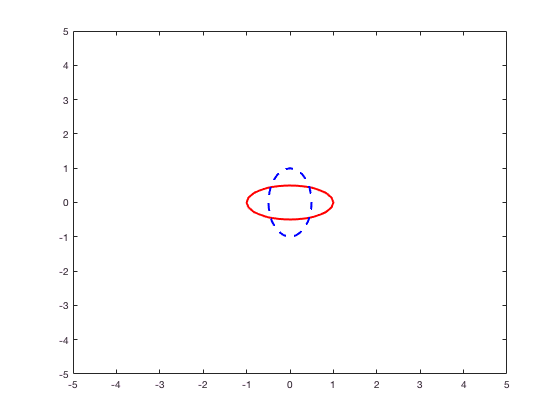

syms x

f(x) = sin(x);
b = -1;
g(x) = f(x - b);

figure;
fplot(f(x), 'Color', 'red');
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');
hold on
fplot(g(x), 'Color', 'blue', 'LineStyle', '--', 'LineWidth', 2);
hold off
legend({'f(x)', sprintf('f(x - %.1f)', b)});

## 1D rotation

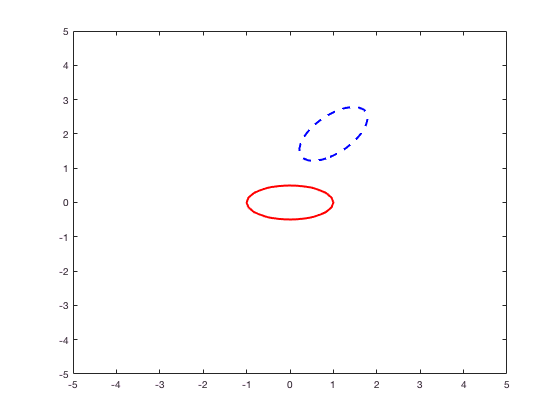

syms x
f(x) = sin(x);
w = -1;
g(x) = f((1/w) * x);

figure;
fplot(f(x), 'Color', 'red');
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');
hold on
fplot(g(x), 'Color', 'blue', 'LineStyle', '--', 'LineWidth', 2);
hold off
legend({'f(x)', sprintf('f(%.1f * x)', 1/w)});

## 1D translation & rotation

syms x
f(x) = sin(x);
w = -1;
b = 1;
g(x) = f(w * x + b);

figure;
fplot(f(x), 'Color', 'red');
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');
hold on
fplot(g(x), 'Color', 'blue', 'LineStyle', '--', 'LineWidth', 2);
hold off
legend({'f(x)', sprintf('f(%.1f * (x - %.1f))', 1/w, b)});

## 2D translation

syms x y
tx = -2;
ty = 2;
f(x, y) = x^2 + (2*y)^2;
g(x, y) = f(x - tx, y - ty);

figure;
fcontour(f(x, y), 'LineWidth', 2, 'LevelList', 1, 'LineColor', 'red')

hold on
fcontour(g(x, y), 'LineWidth', 2, 'LevelList', 1, 'LineColor', 'blue', 'LineStyle', '--')

## 2D rotation

syms x y
theta = pi / 2;
f(x, y) = x^2 + (2*y)^2;
g(x, y) = f(cos(theta) * x + sin(theta) * y, -sin(theta) * x + cos(theta) * y);

figure;
fcontour(f(x, y), 'LineWidth', 2, 'LevelList', 1, 'LineColor', 'red')

hold on
fcontour(g(x, y), 'LineWidth', 2, 'LevelList', 1, 'LineColor', 'blue', 'LineStyle', '--')

## 2D translation and rotation

syms x y
tx = 1;
ty = 2;
theta = pi / 4;
f(x, y) = x^2 + (2*y)^2;
g(x, y) = f(cos(theta) * (x - tx) + sin(theta) * (y - ty), -sin(theta) * (x - tx) + cos(theta) * (y - ty));

figure;
fcontour(f(x, y), 'LineWidth', 2, 'LevelList', 1, 'LineColor', 'red')

hold on
fcontour(g(x, y), 'LineWidth', 2, 'LevelList', 1, 'LineColor', 'blue', 'LineStyle', '--')